$F_c$ - driving force - $[N]$

$\eta_g$ - gearbox efficiency - $[-]$

$K_g$ - gear ratio - $[-]$

$\tau_M$ - motor torque - $[Nm]$

$r_{mp}$ - motor pinion radius (prumer pastorku) - $[m]$


$$F_c = \frac{\eta_g K_g \tau_M}{r_{mp}
}$$


$M_c$- mass of the cart - $[kg]$

$x_C$ - cart position - $[m]$

$B_{eq}$ - equivalent viscous damping coefficient - $[\frac{N m\; s}{rad}]$ 

eta_g = 0.9 %gearbox efficiency

eta_g = 0.9000

K_g = 3.71 %gearbox gear ratio

K_g = 3.7100

k_t = 7.68 %motor current-torque constant

k_t = 7.6800

k_m = 7.68 %motor back-emf constant

k_m = 7.6800

R_m = 2.6 %motor armature resistance

R_m = 2.6000

r_mp = 6.35e-3 %motor pinion radius (prumer pastorku)

r_mp = 0.0064

eta_m = 0.69 %motor efficiency

eta_m = 0.6900

A_m = eta_g * K_g * eta_m * k_t / r_mp / R_m %actuator gain

A_m = 1.0717e+03

J_p = 1.2e-3 %moment of inertia about CoM, medium length pendulum

J_p = 0.0012

L_p = 0.3365 %full length of the pendulum

L_p = 0.3365

l_p = L_p/2

l_p = 0.1683

M_p = 0.127 %pendulum mass

M_p = 0.1270

M_c = 0.38 %cart mass

M_c = 0.3800

J_m = 3.9e-7 %motor moment of inertia

J_m = 3.9000e-07

J_eq = M_c + eta_g*K_g^2*J_m/r_mp^2

J_eq = 0.4998

B_eq = 4.3 %equivalent viscous damping coefficient (cart)

B_eq = 4.3000

B_p = 0.0024 %equivalent viscous damping coefficient (pendulum)

B_p = 0.0024

g = 9.81

g = 9.8100


%syms eta_g K_g k_t k_m R_m r_mp eta_m A_m J_p L_p l_p M_p m_c j_m J_eq B_eq B_p g
syms x_c(t) alpha(t) V_m

%sila pusobici na cart
F_c = (eta_g*K_g*k_t/R_m/r_mp)*(-K_g*k_m*diff(x_c,t)/r_mp + eta_m*V_m) %2.11 LinPendulumGantry

$$F\_c(t) = \frac{471345618602142351\,V_{m}}{439804651110400}-\frac{7603009760930209227\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{1090921693184}$$


%rovnice systemu (2.9 a 2.10 v LinearPendulumGantry)
disp("2.9 a 2.10")

2.9 a 2.10


ode1 = (J_eq+M_p)*diff(x_c,t,2) + M_p*l_p*cos(alpha)*diff(alpha,t,2) - M_p*l_p*sin(alpha)*diff(alpha,t)^2 == F_c - B_eq*diff(x_c,t)

$$ode1(t) = \frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{288230376151711744}-\frac{6158834620015739\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{288230376151711744}+\frac{2822919194634723\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)}{4503599627370496}=\frac{471345618602142351\,V_{m}}{439804651110400}-\frac{38015072259467449591\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{5454608465920}$$

ode2 = M_p*l_p*cos(alpha)*diff(x_c,t,2) + (J_p+M_p*l_p^2)*diff(alpha,t,2) + M_p*l_p*g*sin(alpha) == -B_p*diff(alpha,t)

$$ode2(t) = \frac{1888067738198575\,\sin\left(\alpha \left(t\right)\right)}{9007199254740992}+\frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)}{288230376151711744}+\frac{5528401504798809\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{1152921504606846976}=-\frac{3\,\frac{\partial }{\partial t}\alpha \left(t\right)}{1250}$$

ode1 = subs(ode1, V_m, 0)

$$ode1(t) = \frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{288230376151711744}-\frac{6158834620015739\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{288230376151711744}+\frac{2822919194634723\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)}{4503599627370496}=-\frac{38015072259467449591\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{5454608465920}$$

ode2 = subs(ode2, V_m, 0)

$$ode2(t) = \frac{1888067738198575\,\sin\left(\alpha \left(t\right)\right)}{9007199254740992}+\frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)}{288230376151711744}+\frac{5528401504798809\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{1152921504606846976}=-\frac{3\,\frac{\partial }{\partial t}\alpha \left(t\right)}{1250}$$

odes = [ode1, ode2]

$$odes(t) = \begin{array}{l} \left(\begin{array}{cc} \frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{2}}{288230376151711744}-\frac{6158834620015739\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{288230376151711744}+\frac{2822919194634723\,\sigma_{1}}{4503599627370496}=-\frac{38015072259467449591\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{5454608465920} & \frac{1888067738198575\,\sin\left(\alpha \left(t\right)\right)}{9007199254740992}+\frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{1}}{288230376151711744}+\frac{5528401504798809\,\sigma_{2}}{1152921504606846976}=-\frac{3\,\frac{\partial }{\partial t}\alpha \left(t\right)}{1250} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right) \end{array}$$

[V, S] = odeToVectorField(odes);
vpa(V, 2)

$$ans = \begin{array}{l} \left(\begin{array}{c} Y_{2}\\ \frac{1.3e-5\,\left(3.0e+36\,\cos\left(Y_{1}\right)\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}+9.9e+36\,Y_{2}+8.7e+38\,\sin\left(Y_{1}\right)-9.8e+44\,\cos\left(Y_{1}\right)\,Y_{4}\right)}{\sigma_{1}}\\ Y_{4}\\ -\frac{3.1e-6\,\left(2.7e+36\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}+1.4e+36\,\cos\left(Y_{1}\right)\,Y_{2}+1.2e+38\,\cos\left(Y_{1}\right)\,\sin\left(Y_{1}\right)-8.8e+44\,Y_{4}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3.8e+31\,{\cos\left(Y_{1}\right)}^{2}-2.5e+32 \end{array}$$

odeSystem = matlabFunction(V, 'vars', {'t', 'Y'})

odeSystem = function_handle with value:
    @(t,Y)[Y(2);(sin(Y(1)).*8.664224738358761e+38-cos(Y(1)).*Y(4).*9.820062848972565e+44+Y(2).*9.920033739558008e+36+cos(Y(1)).*sin(Y(1)).*Y(2).^2.*3.010792482713413e+36)./(cos(Y(1)).^2.*3.010792482713413e+36-1.981991301890094e+37);Y(4);((cos(Y(1)).*Y(2).*1.352674373017691e+36+sin(Y(1)).*Y(2).^2.*2.702600527374972e+36+cos(Y(1)).*sin(Y(1)).*1.181434970216743e+38-Y(4).*8.814857612029867e+44).*(-3.149606299212598e-6))./(cos(Y(1)).^2.*3.793124387670441e+31-2.496996915767047e+32)]


sol = ode15s(odeSystem, [0 20], [pi 0.001 0 0])

sol = struct with fields:
     solver: 'ode15s'
    extdata: [1×1 struct]
          x: [1×516 double]
          y: [4×516 double]
      stats: [1×1 struct]
      idata: [1×1 struct]



f1 = figure

f1 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


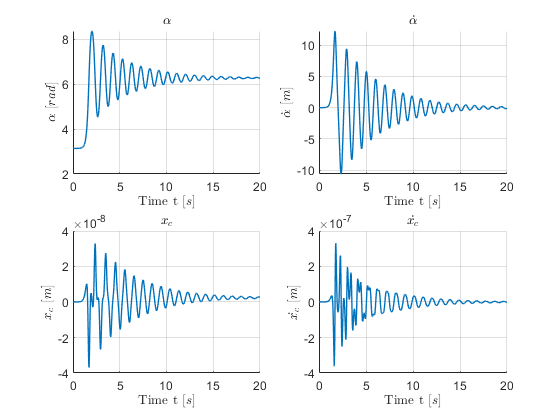

subplot(221);
hold on
grid on
plot(sol.x, sol.y(1,:), "LineWidth", 1)
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\alpha$ [$rad$]', 'Interpreter', 'Latex')
  title('$\alpha$', 'Interpreter', 'Latex')
  
  subplot(222);
hold on
grid on
plot(sol.x, sol.y(2,:), "LineWidth", 1)
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\dot{\alpha}$ [$m$]', 'Interpreter', 'Latex')
  title('$\dot{\alpha}$', 'Interpreter', 'Latex')
  
  subplot(223);
hold on
grid on
plot(sol.x, sol.y(3,:), "LineWidth", 1)
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$x_c$ [$m$]', 'Interpreter', 'Latex')
  title('$x_c$', 'Interpreter', 'Latex')
  
  subplot(224);
hold on
grid on
plot(sol.x, sol.y(4,:), "LineWidth", 1)
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\dot{x_c}$ [$m$]', 'Interpreter', 'Latex')
  title('$\dot{x_c}$', 'Interpreter', 'Latex')